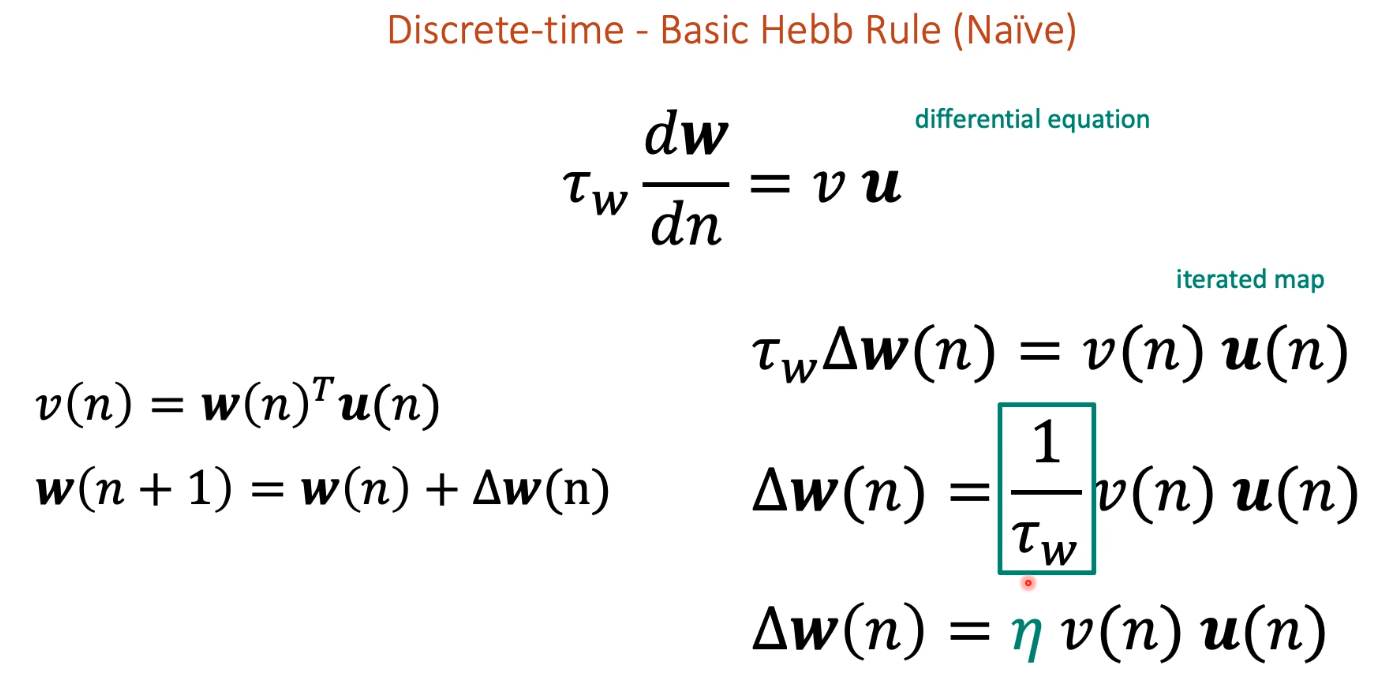

T = readtable(['lab2_1_data.csv']);
X=table2array(T);

eta=0.01;
[w,w_history,norm_history,diff]=hebbian(X,eta,'Naive');

MAX IT
    21



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X'*X;
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

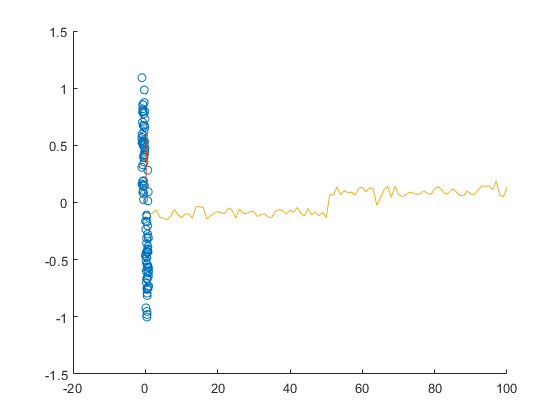

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plot(vec(:,end))
hold off

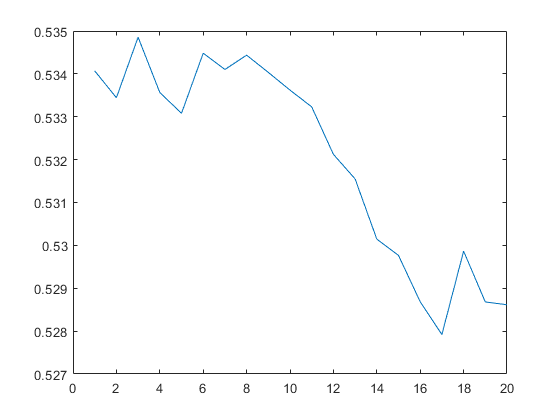

figure
plot([1:length(w_history(1,:))],w_history(1,:))

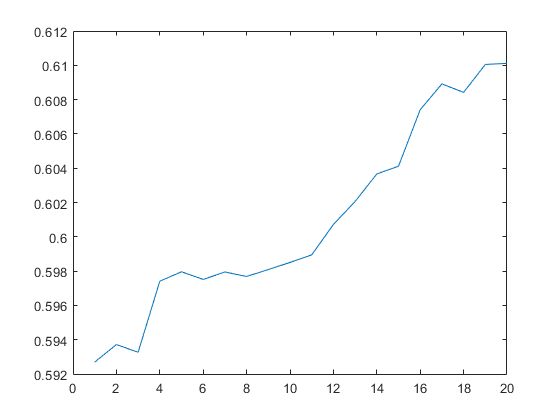

figure
plot([1:length(w_history(2,:))],w_history(2,:))

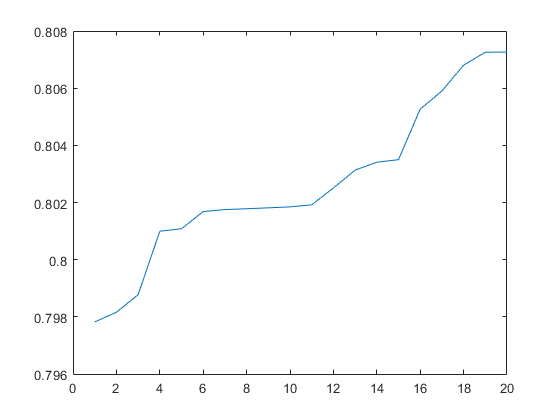

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))


disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Oja');

MAX IT
    50



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X'*X;
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

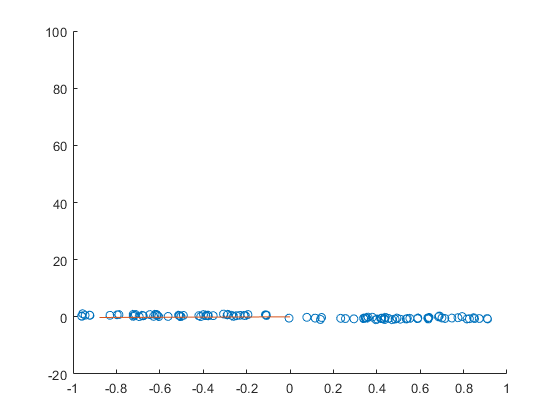

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
%plot(vec(:,end))
plot(eval);
hold off

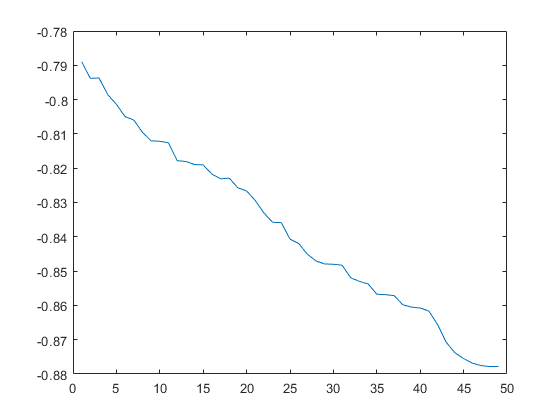

figure
plot([1:length(w_history(1,:))],w_history(1,:))

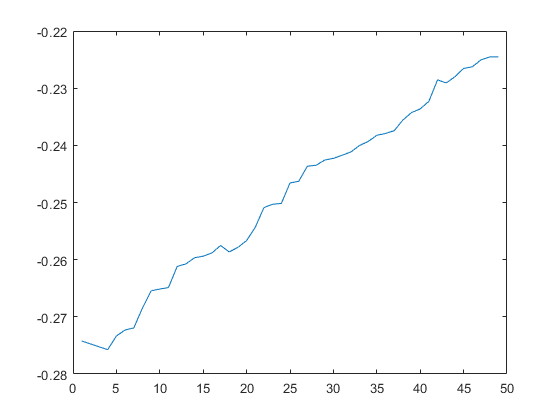

figure
plot([1:length(w_history(2,:))],w_history(2,:))

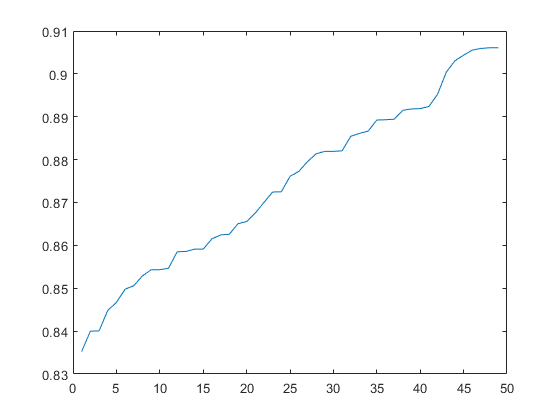

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Sub_Norm');

MAX IT
    53



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X'*X;
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

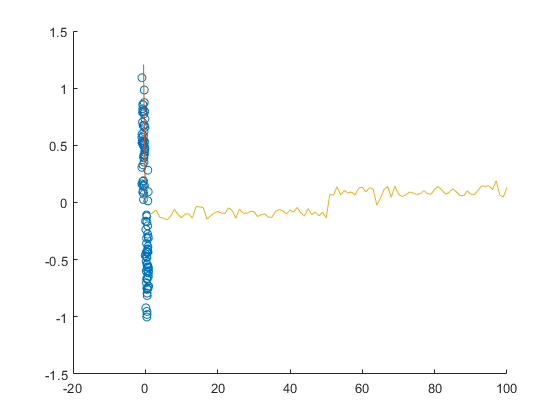

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plot(vec(:,end))
hold off

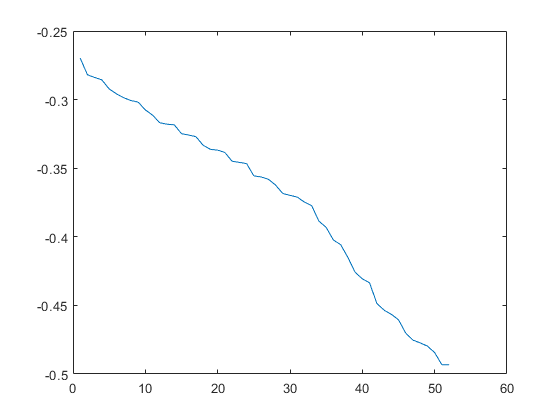

figure
plot([1:length(w_history(1,:))],w_history(1,:))

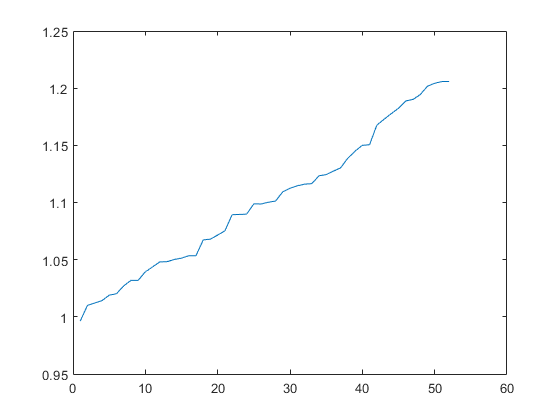

figure
plot([1:length(w_history(2,:))],w_history(2,:))

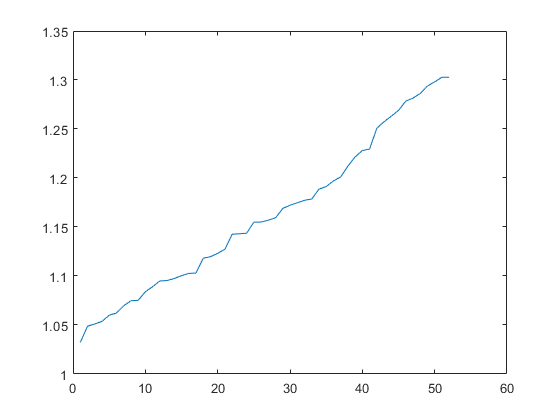

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'BCM');

MAX IT
     3



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X'*X;
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

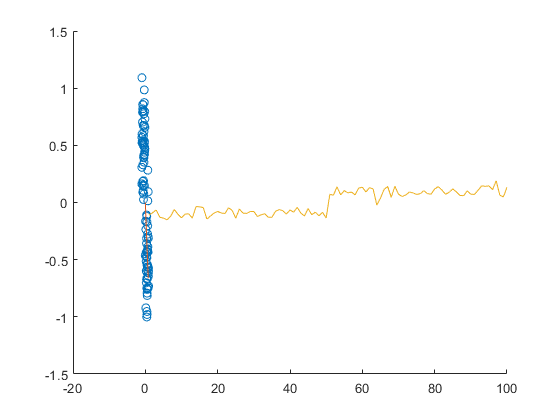

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plot(vec(:,end))
hold off

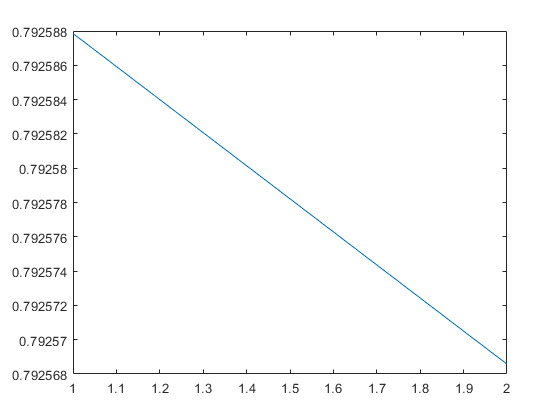

figure
plot([1:length(w_history(1,:))],w_history(1,:))

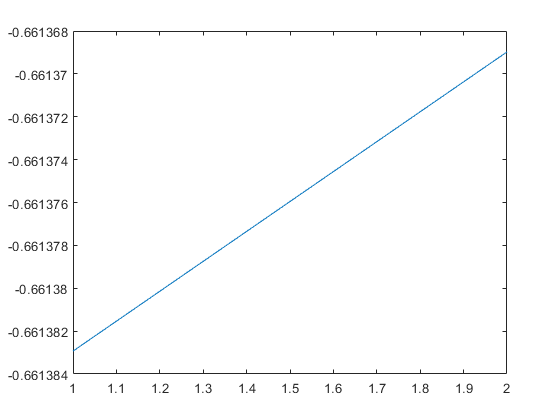

figure
plot([1:length(w_history(2,:))],w_history(2,:))

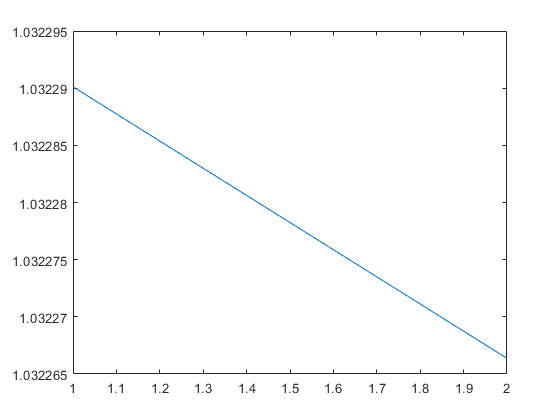

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

disp('--------------------')

--------------------


[w,w_history,norm_history,diff1]=hebbian(X,eta,'Cov');

MAX IT
        1001



scatter(X(1,:),X(2,:))
hold on
plotv(w,'-')
Q=X'*X;
[Evec,Eval]=eig(Q);
maxeval=max(diag(Eval))

maxeval = 58.3095

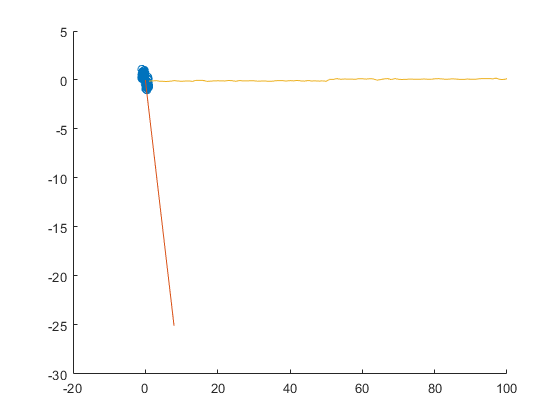

eval=find(diag(Eval)==maxeval);
vec=(Evec(:,eval));
plot(vec(:,end))
hold off

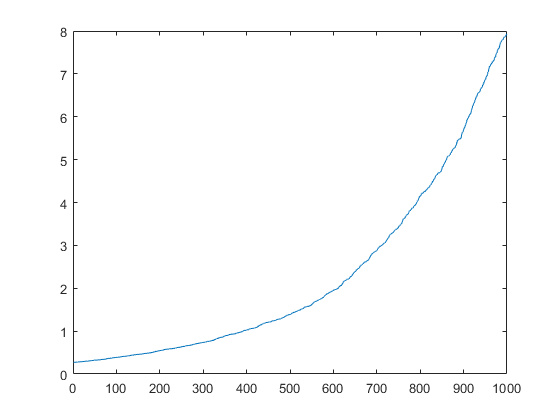

figure
plot([1:length(w_history(1,:))],w_history(1,:))

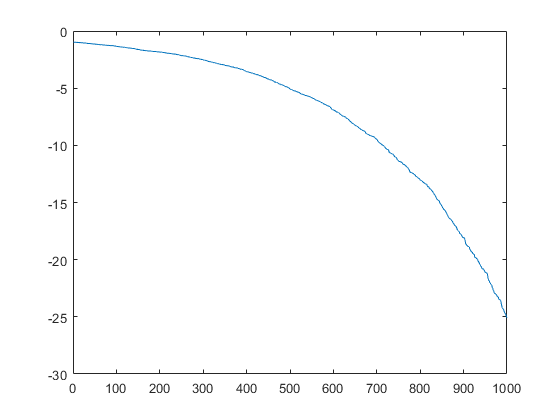

figure
plot([1:length(w_history(2,:))],w_history(2,:))

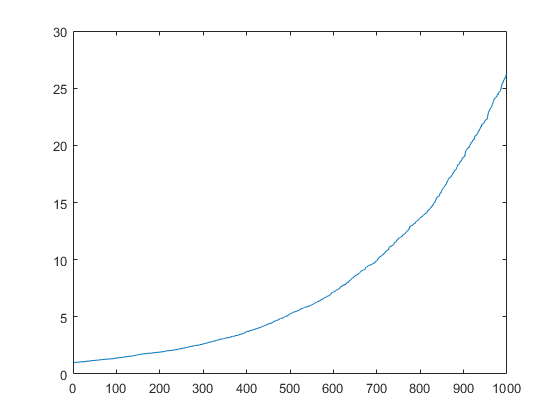

figure
plot([1:length(norm_history(1,:))],norm_history(1,:))

1/tw diventa eta, learning rate. ci dice quanto sia veloce la dinamica[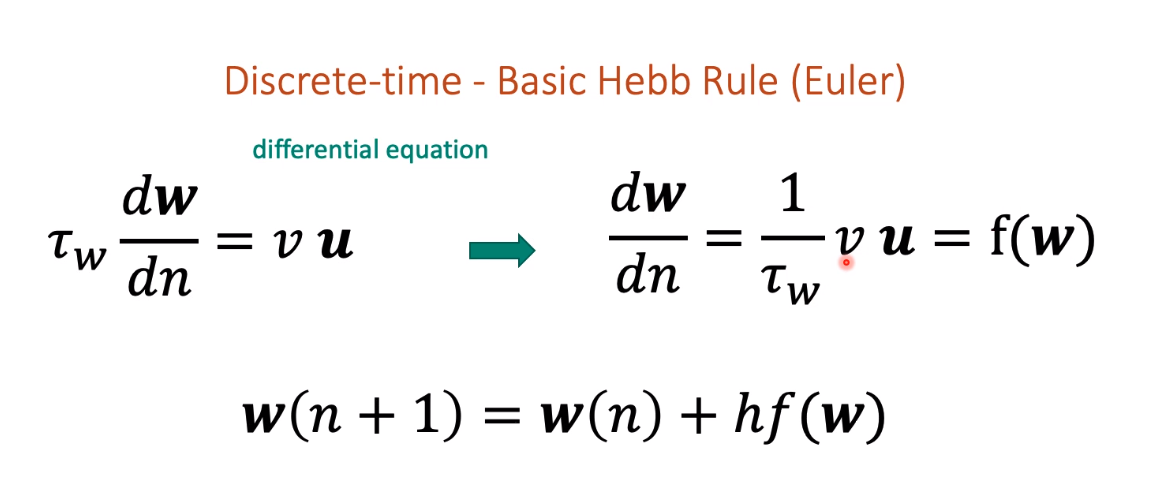

h, small costant(number)

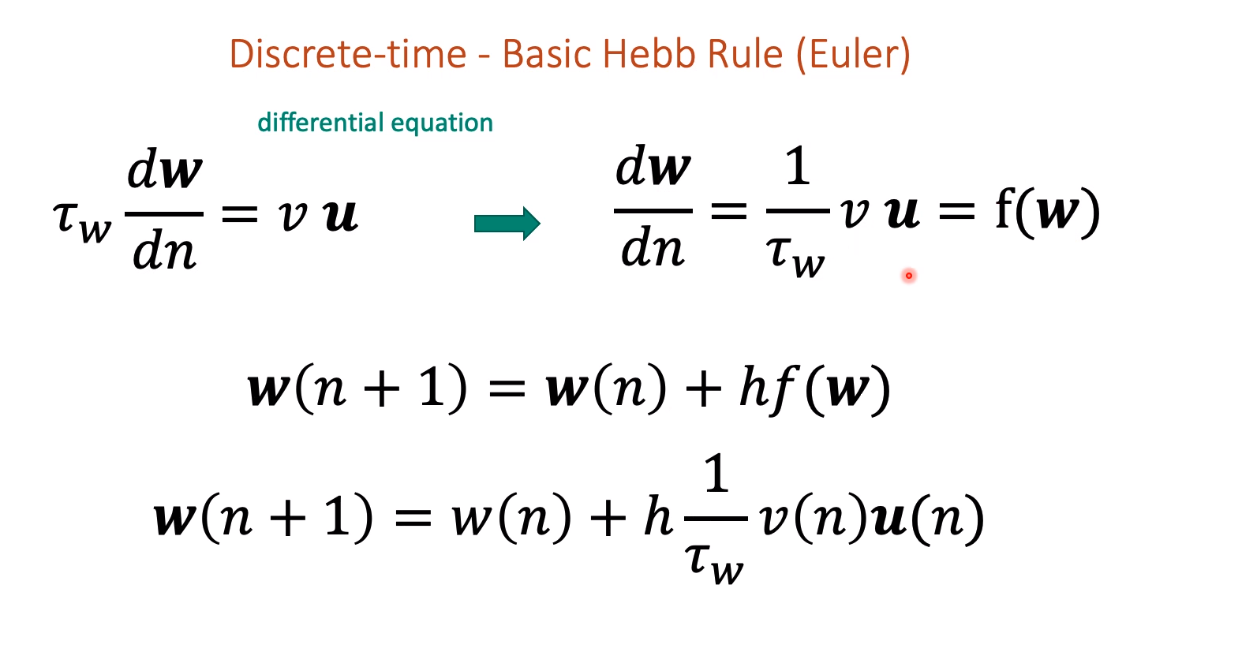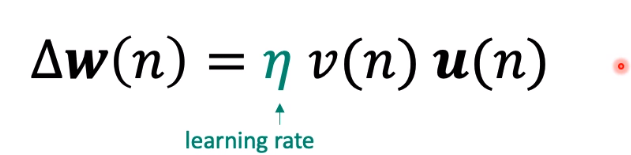

eta now is h*(1/tw)